Q1

A=[1 -1 0 0;
   -1 0 1 0;
   1 0 0 -1;
   0 0 1 -1;
   0 1 0 -1;
   1 1 1 1
    ];
b=[4;9;6;3;7;20];
sol=A\b;
disp(sol)

     5.250000000000000e+00
     4.625000000000001e+00
     9.125000000000002e+00
     1.000000000000000e+00



Q2

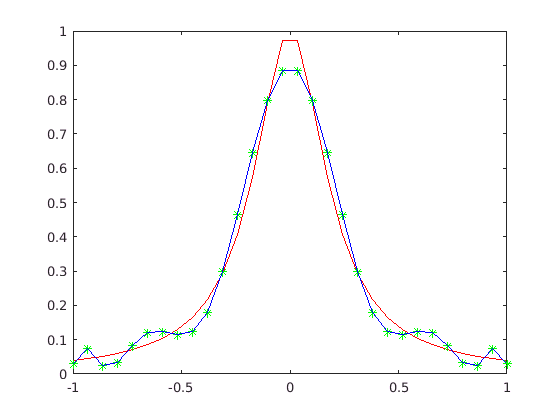

format long e;
n=[30 50 100];
[res1,res2]=solve_Q2(30,10);

fprintf('residual of A\b = %f \n residual of normal =%f\n',res1,res2);

residual of A = 0.216240 
 residual of normal =0.216240


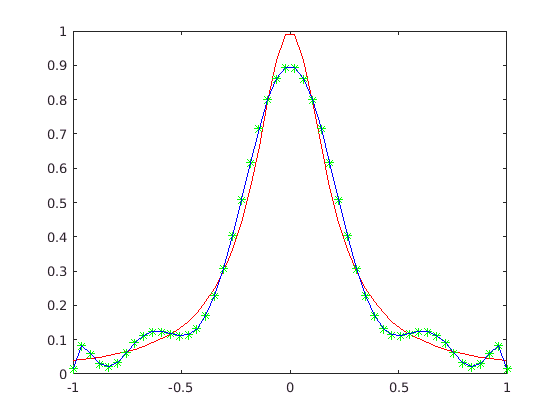

[res1,res2]=solve_Q2(50,10);

fprintf('residual of A\b = %f \n residual of normal =%f\n',res1,res2);

residual of A = 0.283372 
 residual of normal =0.283372


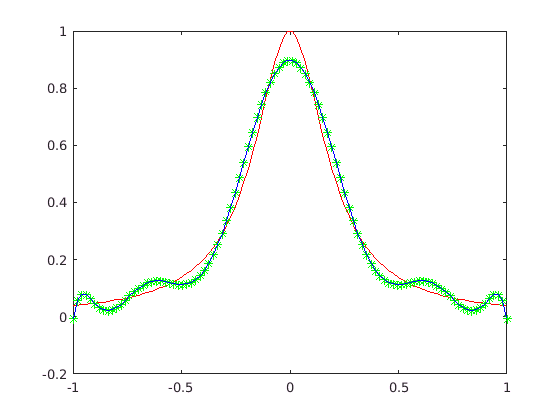

[res1,res2]=solve_Q2(100,10);

fprintf('residual of A\b = %f \n residual of normal =%f\n',res1,res2);

residual of A = 0.399818 
 residual of normal =0.399818


Q3

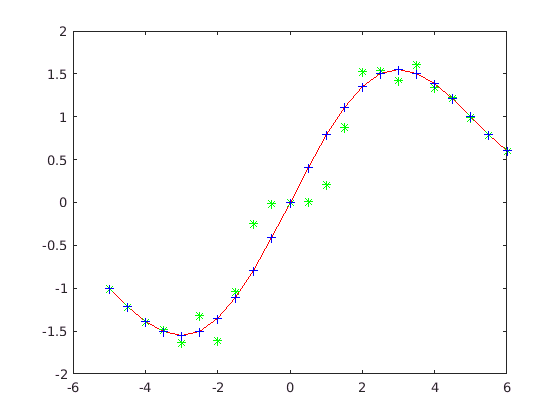

solve_Q3(19);

function [res1,res2]=solve_Q2(n,degree)
        x=linspace(-1,1,n);
        x=x';
        b=1./(1+25*x.*x);
        A=zeros(n,degree+1);
        for i=1:n
           for j=1:degree+1
              A(i,j)=x(i)^(j-1); 
           end
        end 
        sol1=A\b;
        sol2=(A'*A\A'*b);
        values1=polyval(flipud(sol1),x);
        values2=polyval(flipud(sol2),x);
        plot(x,b,'r');
        hold on;
        plot(x,values1,'g*');
        plot(x,values2,'b-');
        hold off;
        res1=norm(values1-b,2);
        res2=norm(values2-b,2);
end


function [res1,res2]=solve_Q3(degree)
        x=-5:0.5:6;
        n=length(x);
        x=x';
        b=sin(pi*x/5)+x/5;
        A=zeros(n,degree+1);
        for i=1:n
           for j=1:degree+1
              A(i,j)=x(i)^(j-1); 
           end
        end 
        m=degree+1;
        B=zeros(m+n);
        B(1:n,1:n)=eye(n);
        B(1:n,n+1:end)=A;
        B(n+1:end,1:n)=A';
        b1=zeros(m+1,1);
        b1(1:n)=x;
        sol3=B\b;
        sol1=A\b;
        sol2=(A'*A\A'*b);
        values1=polyval(flipud(sol1),x);
        values2=polyval(flipud(sol2),x);
        plot(x,b,'r');
        hold on;
        plot(x,values1,'g*');
        plot(x,values2,'b+');
        hold off;
        res1=norm(values1-b,2);
        res2=norm(values2-b,2);
        
end